# Изучение красного смещения звёзд

close all
clear variables

#### 1. Импорт данных

data = readmatrix("data.txt")

data =     4.0000  134.0000  130.0000  115.0000
    3.5000  120.0000  112.0000  101.0000
    3.0000   98.0000   93.0000   81.0000
    2.5000   76.0000   74.0000   66.0000
    2.0000   57.0000   54.0000   53.0000


OX  = data(:, 1);

Y20 = data(:, 2) / 39.8

Y20 =     3.3668
    3.0151
    2.4623
    1.9095
    1.4322


Y30 = data(:, 3) / 40.7

Y30 =     3.1941
    2.7518
    2.2850
    1.8182
    1.3268


Y50 = data(:, 4) / 42.5

Y50 =     2.7059
    2.3765
    1.9059
    1.5529
    1.2471



p1= polyfit(OX, Y20, 1);
p2= polyfit(OX, Y30, 1);
p3= polyfit(OX, Y50, 1);

f1 = polyval(p1, OX);
f2 = polyval(p2, OX);
f3 = polyval(p3, OX);

names = ["T = 20"; "T = 30"; "T = 50"]

names = 3×1 string array
    "T = 20"
    "T = 30"
    "T = 50"


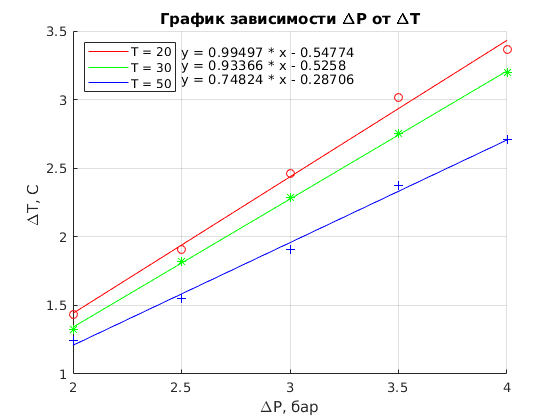

%{
x=[22.0 24.0 27.0 30.0 31.0 35.0 40.0];
y=[1.24 1.37 1.46 1.26 1.66 1.84 1.99];
% Найдем коэффициэнты полинома
a=polyfit(x,y,5),
%  Найдем значения полиномов в интервале от 20 до 40
x1=20:0.5:40;
y1=polyval(a,x1);
y0 = polyval(a,x); % расчет ф-ции в точках данных
% Погрешность аппроксимации по МНК
e=sum((y0-y).^2)/length(y)
%}



graph = figure;

hold on;

    plot(OX, f1, 'r-');
    plot(OX, f2, 'g-');
    plot(OX, f3, 'b-');
    plot(data(:, 1), Y20, 'ro');
    plot(data(:, 1), Y30, 'g*');
    plot(data(:, 1), Y50, 'b+');
hold off;

set   (graph, 'Visible', 'on'); 
xlabel('\DeltaP, бар');
ylabel('\DeltaT, C ');
title ('График зависимости \DeltaP от \DeltaT');
legend('T = 20', 'T = 30', 'T = 50', 'Location','northwest');
text(2.5, 3.35, ['y = ', num2str(p1(1)), ' * x - ', num2str(-p1(2))]);
text(2.5, 3.25, ['y = ', num2str(p2(1)) , ' * x - ', num2str(-p2(2))]);
text(2.5, 3.15, ['y = ', num2str(p3(1)), ' * x - ', num2str(-p3(2))]);
grid on; 



saveas(graph, 'graph.png');

#### 6. Построение графика спектров всех звёзд

%graphStars = figure;

%hold on;
%for indxGraph = 1 : numStars
%    if speed(indxGraph) > 0
%        plot(lambda, spectra(:, indxGraph), ...
%             '-', ...
%             'Linewidth', 3);
%    else 
%        plot(lambda, spectra(:, indxGraph), ...
%             '--', ...
%             'Linewidth', 1); 
%    end
%end
%hold off;

#### 7. Добавление на график названия, подписи осей, сетки и легенды

%set   (graphStars, 'Visible', 'on'); 
%xlabel('Длина волны, нм');
%ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
%title ('Спектры звёзд');
%legend(starNames);
%grid on;
%saveas(graphStars, 'spectra.png');